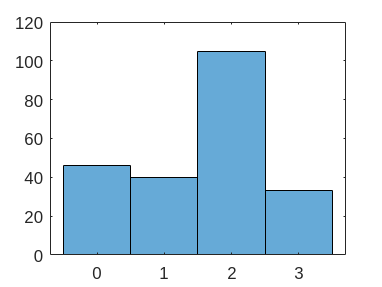

dataFiles = dir("Python_Data/*.mp4");

labelData = [];
labelFiles = strings;

for fileID = 1:length(dataFiles)
    videoFilename = dataFiles(fileID).name;

    tokExtFilename = strsplit(videoFilename, ".");
    labelFilename = strcat(tokExtFilename{1}, "_LABELS.txt");

    tokFilename = strsplit(videoFilename, '_');
    classStr = tokFilename{2};
    classID = -1;

    if strcmp(classStr, 'AIRPLANE')
        classID = 0;
    elseif strcmp(classStr, 'BIRD')
        classID = 1;
    elseif strcmp(classStr, 'DRONE')
        classID = 2;
    elseif strcmp(classStr, 'HELICOPTER')
        classID = 3;
    end

    labelData = [labelData; classID];
    labelFiles = [labelFiles; labelFilename];

end

labelFiles = labelFiles(2:end, :);

rng('default')
n = length(labelData);
dataPartition = cvpartition(n, 'Holdout', 0.3);

idxTrain = training(dataPartition);
dataTrain = dataFiles(idxTrain, :);
labelTrain = labelData(idxTrain, :);
labelTrainFiles = labelFiles(idxTrain, :);

idxTest = test(dataPartition);
dataTest = dataFiles(idxTest, :);
labelTest = labelData(idxTest, :);
labelTestFiles = labelFiles(idxTest, :);

figure(1)
histogram(labelData)

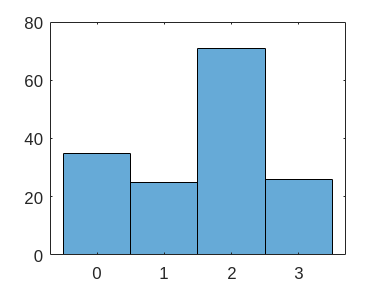


figure(2)
histogram(labelTrain)

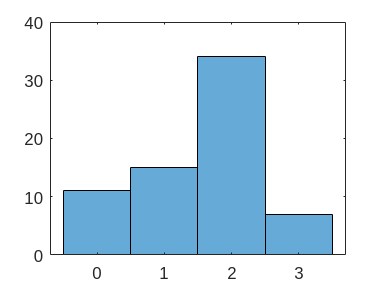


figure(3)
histogram(labelTest)


dataDir = "Python_Data/";
trainDir = "Python_Data/train_videos";
testDir = "Python_Data/test_videos";

% mkdir(trainDir);
% mkdir(testDir);

for trainID = 1:length(dataTrain)
    dataFile = dataTrain(trainID).name;
    labelFile = labelTrainFiles(trainID);

    dataPath = strcat(dataDir, dataFile);
    labelPath = strcat(dataDir, labelFile);

    dataStatus = movefile(dataPath, trainDir);
    labelStatus = movefile(labelPath, trainDir);
end

for testID = 1:length(dataTest)
    dataFile = dataTest(testID).name;
    labelFile = labelTestFiles(testID);

    dataPath = strcat(dataDir, dataFile);
    labelPath = strcat(dataDir, labelFile);

    dataStatus = movefile(dataPath, testDir);
    labelStatus = movefile(labelPath, testDir);
end